clear; clc; close all

% Riproducibilità
rng(42);

% Caricamento immagini
path = fullfile('Dataset', 'Da usare');
imgs = imageDatastore(path, "IncludeSubfolders", true, "LabelSource", "foldernames");

path2 = fullfile('Dataset', 'Da usare1');
imgs2 = imageDatastore(path2, "IncludeSubfolders", true, "LabelSource", "foldernames");

# EDA

Dataset principale: "[COCO 2017 Unlabeled Images](https://cocodataset.org/#download)", contiene un po' di tutto

Dataset contro-test: "[Sea Animals Image Dataset🌊](https://www.kaggle.com/datasets/vencerlanz09/sea-animals-image-dataste)" + "[Count Coins Image dataset](https://www.kaggle.com/datasets/balabaskar/count-coins-image-dataset)", mix di animali marini e monete

Entrambi i dataset utilizzati sono un sottoinsieme degli originali, questo perché le immagini che risultavano sfocate già in partenza sono state rimosse per evitare problemi. 

([Blur detection with OpenCV](https://pyimagesearch.com/2015/09/07/blur-detection-with-opencv/))

Il dataset principale inoltre è stato limitato a `60000` immagini per ridurre il tempo di addestramento complessivo pur mantenendo un buon numero di elementi.

A grandi linee la preparazione del dataset è stata la seguente:

- Apri immagine in scala di grigi

- Se troppo piccola/sfocata passa alla successiva

- Applica la convoluzione con kernel casuale

- Ritaglia una porzione di dimensione 224x224

- Salva risultato

fprintf("Dataset principale");

Dataset principale

fprintf('Numero totale di immagini: %d\n', numel(imgs.Labels));

Numero totale di immagini: 60000


fprintf('Training: %d\n', numel(imgs.Labels) * 0.7);

Training: 42000


fprintf('Validazione: %d\n', numel(imgs.Labels) * 0.15);

Validazione: 9000


fprintf('Test: %d\n\n', numel(imgs.Labels) * 0.15);

Test: 9000



% 
% % Immagini per classe
% figure;
% 
% countcats(imgs.Labels);
% histogram(imgs.Labels);
% 
% title('Numero di immagini per classe');
% ylim([5200, 5600]);
% 
% ax = gca;
% ax.YAxis.Exponent = 0;
% ytickformat('%.0f')
% 
% xtickangle(45);
% 
% grid on;
% 
% 
% % Boxplot del laplaciano per classe
% figure;
% 
% T = readtable(fullfile(path, 'blur_scores.csv'), ...
%     'Delimiter', ',', ...
%     'ReadVariableNames', true, ...
%     'VariableNamingRule', 'preserve');
% 
% T.kernel = categorical(T.kernel);
% T.kernel = reordercats(T.kernel, sort(categories(T.kernel)));
% 
% boxplot(T.blur_score_dopo, T.kernel);
% set(gcf, 'Position', [100, 100, 600, 700]);
% 
% set(gca,'YScale', 'log')
% 
% ax = gca;
% ax.TickLabelInterpreter = 'tex';
% 
% title('Varianza del Laplaciano per classe');
% 
% xtickangle(45);
% grid on;
% 
% fprintf(['L''asse delle ordinate usa la scala logaritmica a causa dell''enorme\n' ...
%     'differenza tra i valori della classe "Originale" e tutte le altre']);
% 
% 
% fprintf('%s\n', repmat(' ', 1, 80));
% % Altro dataset
% 
fprintf('Secondo dataset');

Secondo dataset

fprintf('Numero totale di immagini: %d\n', numel(imgs2.Labels));

Numero totale di immagini: 1360


% 
% % Immagini per classe
% figure;
% 
% countcats(imgs2.Labels);
% histogram(imgs2.Labels);
% 
% title('Numero di immagini per classe');
% ylim([100, 140]);
% 
% ax = gca;
% ax.YAxis.Exponent = 0;
% ytickformat('%.0f')
% 
% xtickangle(45);
% 
% grid on;
% 
% 
% % Boxplot del laplaciano per classe
% figure;
% 
% T = readtable(fullfile(path2, 'blur_scores.csv'), ...
%     'Delimiter', ',', ...
%     'ReadVariableNames', true, ...
%     'VariableNamingRule', 'preserve');
% 
% T.kernel = categorical(T.kernel);
% T.kernel = reordercats(T.kernel, sort(categories(T.kernel)));
% 
% boxplot(T.blur_score_dopo, T.kernel);
% 
% set(gcf, 'Position', [100, 100, 600, 700]);
% 
% set(gca,'YScale', 'log')
% 
% ax = gca;
% ax.TickLabelInterpreter = 'tex';
% 
% title('Varianza del Laplaciano per classe');
% 
% xtickangle(45);
% grid on;
% 
% fprintf('Stesso discorso anche qui, i valori sono tuttavia più sparsi');

# Struttura della rete

Cosa non ha funzionato:

- Solo 2 strati convoluzionali

- Average Pooling

- Min Pooling

- Global Average Pooling

- Softplus

- Filtri più grandi dopo il primo strato

- Troppi filtri 

- ADAM

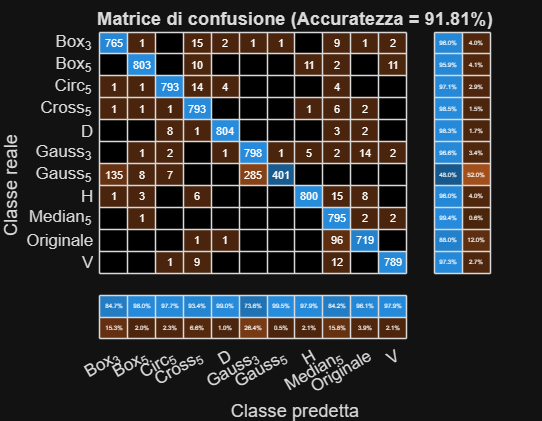

% Servono solo quelle di test
[~ , imgsTemp] = splitEachLabel(imgs, 0.7, "randomized");
[~, imgsTest] = splitEachLabel(imgsTemp, 0.5, "randomized");

% Carica la cnn addestrata
S = load('rete11.mat');

% Mostra struttura
% lgraph = layerGraph(S.layers);
% figure;
% plot(lgraph)
% title('Architettura della CNN');

% Mostra attivazioni
% I = readimage(imgsTest, 1);
% 
% figure
% imshow(I)
% title('Immagine di input')
% 
% for i = 1:numel(S.net.Layers)
% 
%     try
%         A = activations(S.net, I, i, 'OutputAs', 'channels');
% 
%         if ndims(A)==3
% 
%             figure('Units', 'normalized', 'OuterPosition', [0 0 1 1])
%             montage(mat2gray(A), ...
%                     'Size', [NaN 4], ...
%                     'ThumbnailSize', [128 128], ...
%                     'BorderSize', [1 1]);
%             title(sprintf('%d - %s', ...
%                 i, erase(class(S.net.Layers(i)), 'nnet.cnn.layer.')))
% 
%         end
% 
%     catch
%     end
% 
% end
%
%% Predizione della rete
%YPred = classify(S.net, I);
% 
% % Etichetta reale
% YTrue = imgsTest.Labels(1);
% 
% % Confronto
% if YPred == YTrue
%     risultato = 'CORRETTA';
% else
%     risultato = 'ERRATA';
% end
% 
% title(sprintf('Predetta: %s | Reale: %s | %s', ...
%     string(YPred), string(YTrue), risultato))


% Matrice di confusione
YPred = classify(S.net, imgsTest);
YTest = imgsTest.Labels;

accuracy = mean(YPred == YTest);

figure('Position', [100 100 900 700]);
cm = confusionchart(YTest, YPred);
cm.RowSummary = 'row-normalized';
cm.ColumnSummary = 'column-normalized';
cm.XLabel = 'Classe predetta';
cm.YLabel = 'Classe reale';
colormap(parula)
title(sprintf('Matrice di confusione (Accuratezza = %.2f%%)', accuracy * 100));


%% Metriche di valutazione
C = confusionmat(YTest, YPred);

TP = diag(C);
FP = sum(C,1)' - TP;
FN = sum(C,2) - TP;
TN = sum(C(:)) - TP - FP - FN;

precision  = TP ./ (TP + FP);
recall     = TP ./ (TP + FN);
specificity = TN ./ (TN + FP);
f1         = 2 * (precision .* recall) ./ (precision + recall);

% Media delle metriche
precisionMean  = mean(precision,'omitnan');
recallMean     = mean(recall,'omitnan');
specificityMean = mean(specificity,'omitnan');
f1Mean         = mean(f1,'omitnan');

fprintf('\n===== Metriche complessive =====\n');


===== Metriche complessive =====


fprintf('Precisione media  : %.2f%%\n', precisionMean*100);

Precisione media  : 92.92%


fprintf('Recall medio      : %.2f%%\n', recallMean*100);

Recall medio      : 91.92%


fprintf('Specificità media : %.2f%%\n', specificityMean*100);

Specificità media : 99.18%


fprintf('F1-Score medio    : %.2f%%\n\n', f1Mean*100);

F1-Score medio    : 91.34%




% Metriche per classe
T = table(categories(YTest), specificity, f1, ...
    'VariableNames', {'Classe','Specificità','F1-Score'});

disp(T);

       Classe        Specificità    F1-Score
    _____________    ___________    ________

    {'Box_3'    }      0.98317          0.9 
    {'Box_5'    }      0.99804      0.96981 
    {'Circ_5'   }      0.99768       0.9736 
    {'Cross_5'  }      0.99316      0.95889 
    {'D'        }      0.99902       0.9865 
    {'Gauss_3'  }        0.965       0.8356 
    {'Gauss_5'  }      0.99975       0.6473 
    {'H'        }      0.99792       0.9697 
    {'Median_5' }      0.98182       0.9117 
    {'Originale'}      0.99645      0.91885 
    {'V'        }      0.99792      0.97588 



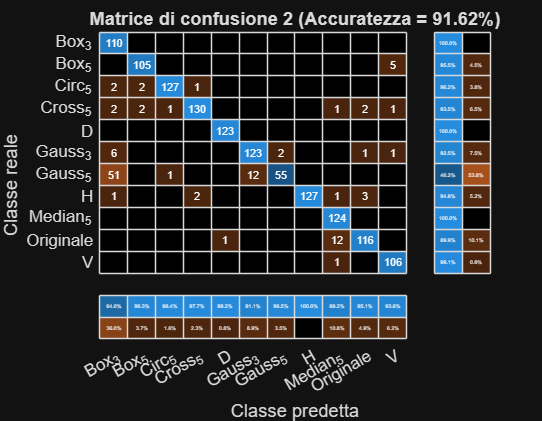


% Secondo dataset
YPred2 = classify(S.net, imgs2);
YTest2 = imgs2.Labels;

accuracy2 = mean(YPred2 == YTest2);

figure('Position', [100 100 900 700]);
cm2 = confusionchart(YTest2, YPred2);
cm2.RowSummary = 'row-normalized';
cm2.ColumnSummary = 'column-normalized';
cm2.XLabel = 'Classe predetta';
cm2.YLabel = 'Classe reale';
colormap(parula)
title(sprintf('Matrice di confusione 2 (Accuratezza = %.2f%%)', accuracy2 * 100));


%% Metriche di valutazione 2
C = confusionmat(YTest2, YPred2);

TP = diag(C);
FP = sum(C,1)' - TP;
FN = sum(C,2) - TP;
TN = sum(C(:)) - TP - FP - FN;

precision  = TP ./ (TP + FP);
recall     = TP ./ (TP + FN);
specificity = TN ./ (TN + FP);
f1         = 2 * (precision .* recall) ./ (precision + recall);

% Media delle metriche
precisionMean  = mean(precision,'omitnan');
recallMean     = mean(recall,'omitnan');
specificityMean = mean(specificity,'omitnan');
f1Mean         = mean(f1,'omitnan');

fprintf('\n===== Metriche complessive =====\n');


===== Metriche complessive =====


fprintf('Precisione media  : %.2f%%\n', precisionMean*100);

Precisione media  : 92.85%


fprintf('Recall medio      : %.2f%%\n', recallMean*100);

Recall medio      : 91.61%


fprintf('Specificità media : %.2f%%\n', specificityMean*100);

Specificità media : 99.17%


fprintf('F1-Score medio    : %.2f%%\n\n', f1Mean*100);

F1-Score medio    : 91.01%




% Metriche per classe
T = table(categories(YTest2), specificity, f1, ...
    'VariableNames', {'Classe','Specificità','F1-Score'});

disp(T);

       Classe        Specificità    F1-Score
    _____________    ___________    ________

    {'Box_3'    }       0.9504      0.78014 
    {'Box_5'    }       0.9968       0.9589 
    {'Circ_5'   }      0.99837      0.97318 
    {'Cross_5'  }      0.99754      0.95588 
    {'D'        }      0.99919      0.99595 
    {'Gauss_3'  }      0.99022      0.91791 
    {'Gauss_5'  }      0.99839        0.625 
    {'H'        }            1      0.97318 
    {'Median_5' }      0.98786      0.94297 
    {'Originale'}      0.99513       0.9243 
    {'V'        }      0.99441      0.96364 

